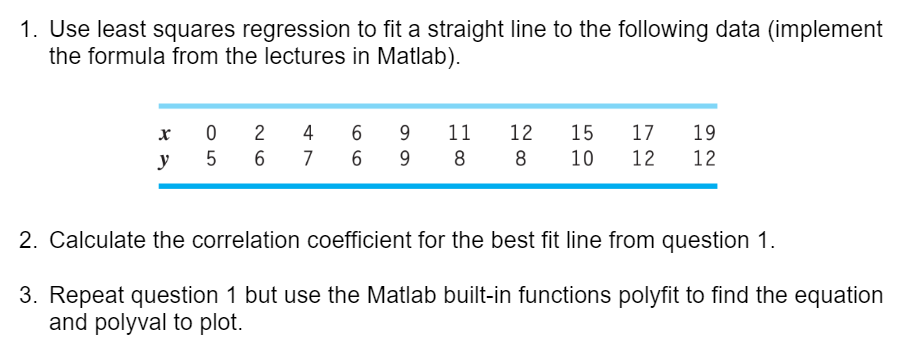

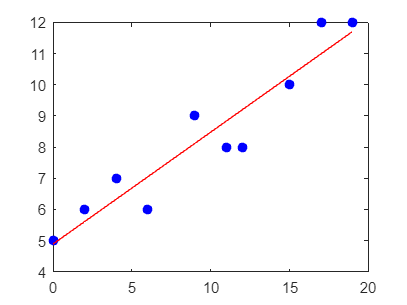

% Question 1
%Always plot data points first.
x = [0, 2, 4, 6, 9, 11, 12, 15, 17, 19];
y = [5, 6, 7, 6, 9, 8, 8, 10, 12, 12];
plot(x, y, 'ob', 'MarkerFaceColor','b');
hold on;
%get coefficients for linear realtionship. Then plot them such that it is
%x, y.. Y = a0 + a1(x).
[a0, a1] = LeastRegression(x, y);
plot(x, (a0 + (a1*x)), '-r');
hold off;

disp(['a0 = ', num2str(a0)]);

a0 = 4.8881


disp(['a1 = ', num2str(a1)]);

a1 = 0.35915



%For a certain data points, get Correlation Coeff by function.
% Question 2
r = CorrelationCoeff(x, y);
disp(['r = ', num2str(r)]);

r = 0.94493


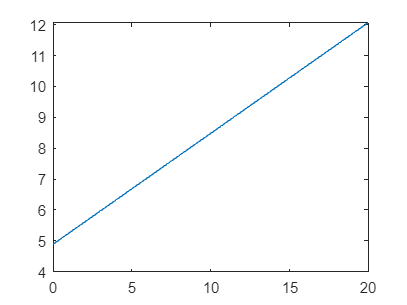


poly_fitted = polyfit(x, y, 1);
x_axis = linspace(0, 20);
y_axis = polyval(poly_fitted, x_axis);
plot(x_axis, y_axis);

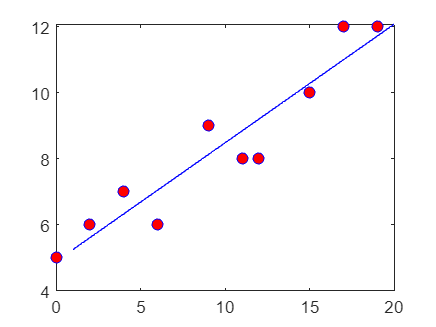

%Question 3
x = [0, 2, 4, 6, 9, 11, 12, 15, 17, 19];
y = [5, 6, 7, 6, 9, 8, 8, 10, 12, 12];
plot(x, y, 'ob', 'MarkerFaceColor','r');
hold on;
a = polyfit(x, y, 1); % get coeefficients without least regreession
x_values = linspace(1, 20);
y_values = polyval(a, x_values); %get y values for a linspace range BASED on coeff

plot(x_values, y_values, '-b');
hold off;

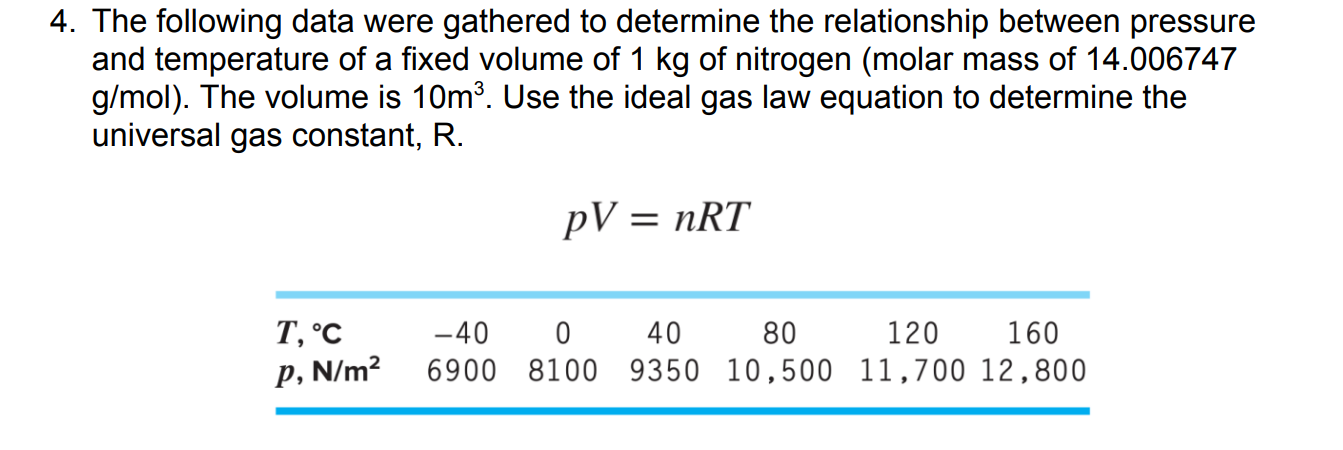

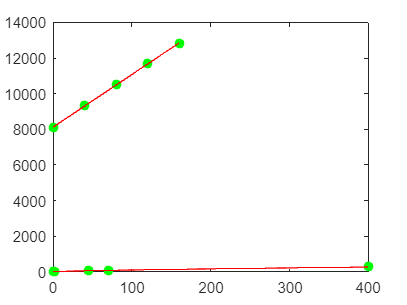

%Question 4
%GENERAL RULE: Plot points, get coeff, get X over range, Y. Then final plot
T =  [-40 0 40 80 120 160];
p = [6900 8100 9350 10500 11700 12800];
plot(T, p, 'og', 'MarkerFaceColor', 'g');
hold on;
a = polyfit(T, p, 1);
x_values = linspace(-40, 160);
y_values = polyval(a, x_values);
plot(x_values, y_values, '-r');
hold off;

%substitution of original formula
n = 1000/14.006747;
V = 10*2;
m = a(1);
R = (V*m)/n;
disp(['Value of R = ', num2str(R)]);

Value of R = 8.294


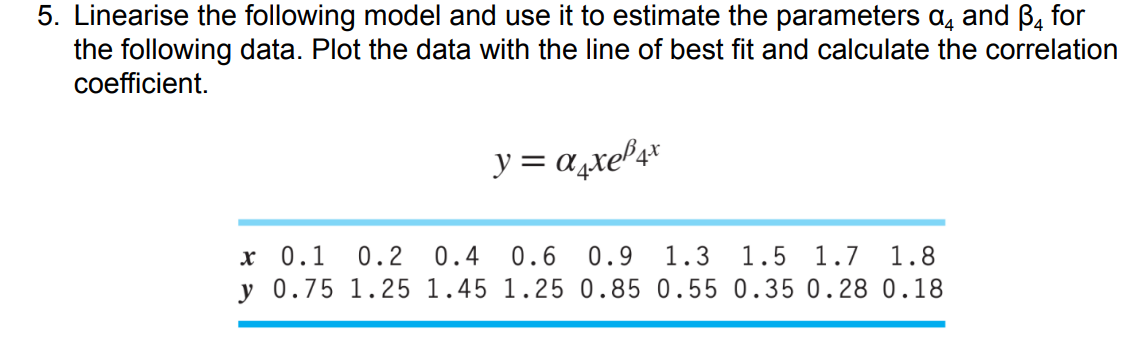

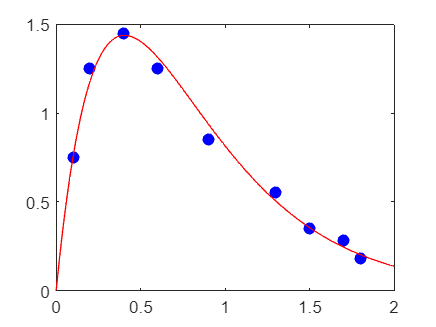

%Question 5
%Plot points, get coeff, by LINEARISING diff function
%If diff function has value not multiplied by log, you take it as it is and
%DONT LOG IT, just try to manipulate the logged version alr. 
%Then you get X, Y(multiplying coeff WITH ORIGINAL EQ )(NON
%LINEAR) IN THE FORM THAT COEFF ARE CORRECTLY PLACED. DONT POLYVAL.

x = [0.1 0.2 0.4 0.6 0.9 1.3 1.5 1.7 1.8];
y = [.75 1.25 1.45 1.25 .85 .55 .35 .28 .18];
plot(x,y,'ob', 'MarkerFaceColor','b');
hold on;
a = polyfit(x, log(y./x), 1);
a(2) = exp(a(2));
X = linspace(0, 2);
Y = a(2).*X.*exp(a(1)*X);
plot(X, Y, '-r');

b = a(1);
n = length(x);
numerator = n * sum(x .* log(y ./ x)) - sum(x) * sum(log(y ./ x));
denominator_x = sqrt(n * sum(x.^2) - sum(x)^2);
denominator_y = sqrt(n * sum(log(y ./ x).^2) - sum(log(y ./ x))^2);
r = numerator / (denominator_x * denominator_y);
disp(['Pearson Correlation Coefficient (r): ', num2str(r)]);

Pearson Correlation Coefficient (r): -0.99868


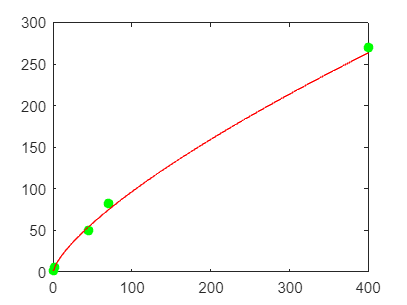

%Question 6
x = [.16 .3 2 45 70 400];
y = [.97 1.45 4.8 50 82 270];
names = ['Dove', 'Rat', 'Hen', 'Sheep', 'Human', 'Cow'];
plot(x, y, 'og', 'MarkerFaceColor', 'g');
hold on;
a = polyfit(log10(x), log10(y), 1);
a(2) = 10^(a(2));
X = linspace(0, 410);
Y = a(2)*X.^a(1);
plot(X, Y, '-r'); hold on;
xlim([0, 400]);

MetabolismY = a(2)*200^a(1);
disp(['Bolism of Tiger at 200kg: ', num2str(MetabolismY)]);

Bolism of Tiger at 200kg: 159.2047


%Question 7

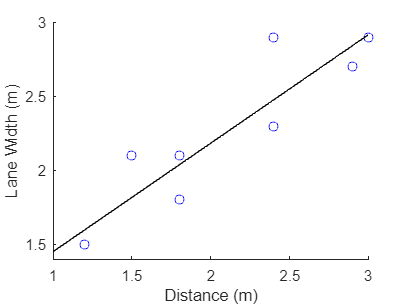

%Question 8
clear;
clc;
figure;
x = [2.4 1.5 2.4 1.8 1.8 2.9 1.2 3 1.2];
y = [2.9 2.1 2.3 2.1 1.8 2.7 1.5 2.9 1.5];
hold on;
plot(x, y, 'bo');
a = polyfit(x, y, 1);
X = linspace(1, 3);
Y = polyval(a, X);
plot(X, Y, '-k');
xlabel('Distance (m)');
ylabel('Lane Width (m)');

MinWidth = a(1)*1.8 + 0.7167;

function [a0, a1] = LeastRegression(x, y)
    n = length(x);
    s1 = sum(x .* y) - (sum(x) * sum(y)) / n;
    s2 = sum(x.^2) - (sum(x)^2) / n;
    a1 = s1 / s2;
    a0 = mean(y) - a1 * mean(x);
end

function [r] = CorrelationCoeff(x,y)
    n = length(x);
    s1 = sum(x .* y) - (sum(x) * sum(y)) / n;
    s2 = sqrt(sum(x.^2) - (sum(x)^2) / n) * sqrt(sum(y.^2) - (sum(y)^2) / n);
    r = s1 / s2;
end